# Tuneable Parameters

% Simulation parameters
dt = 1;  % time step (s)
num_iterations = 100; % Number of time steps
num_vehicles = 10; % Number of vehicles 

% generate_traffic_signal_states
red_time = 20; % Red light duration (s)
yellow_time = 3.5; % Yellow light duration (s)
green_time = 20; % Green light duration (s)
d_stop_line = 300; % Stop line position (m)
probability_stop = 0.5; % Probability of stopping in dilemma zone

% IDM parameters
params.v_desired = 15;  % desired speed (m/s)
params.a_max = 1.0;     % maximum acceleration (m/s^2)
params.b = 1.5;         % comfortable deceleration (m/s^2)
params.s0 = 2.0;        % minimum gap (m)
params.T = 1.0;         % safe time headway (s)
params.delta = 4;       % acceleration exponent

% Acceleration noise
acceleration_noise_bound = 1;  % Uniform distribution U[-acceleration_noise_bound, acceleration_noise_bound]

#  generate_traffic_signal_states

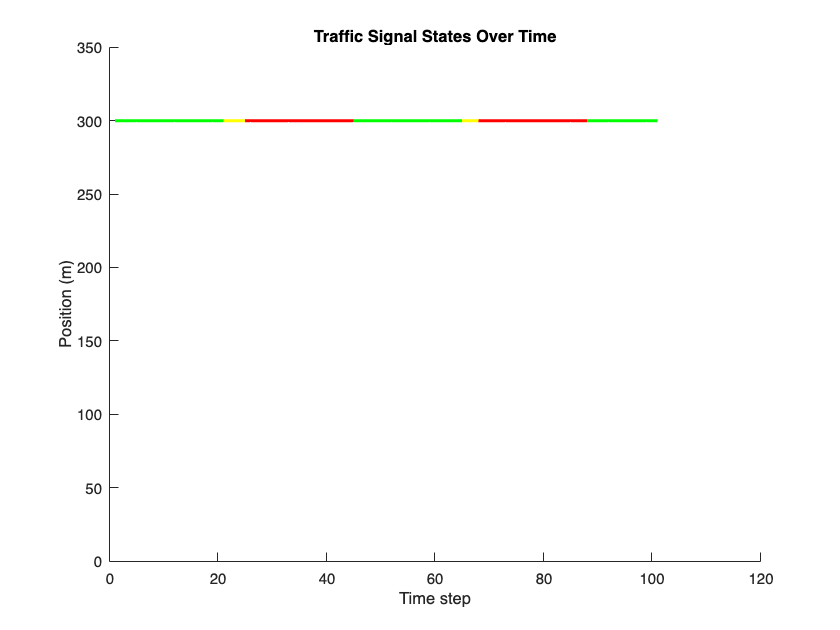

% Generate traffic signal states
[traffic_signal_states, ~] = generate_traffic_signal_states(num_iterations, red_time, yellow_time, green_time, num_vehicles);

% Plot traffic light state as a horizontal line at y = d_stop_line
figure;
hold on;

for k = 1:num_iterations
    if traffic_signal_states(k) == "red"
        plot([k k+1], [d_stop_line d_stop_line], 'r', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "yellow"
        plot([k k+1], [d_stop_line d_stop_line], 'y', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "green"
        plot([k k+1], [d_stop_line d_stop_line], 'g', 'LineWidth', 2);
    end
end

xlabel('Time step');
ylabel('Position (m)');
title('Traffic Signal States Over Time');
ylim([0 d_stop_line + 50]);
hold off;

# IDM

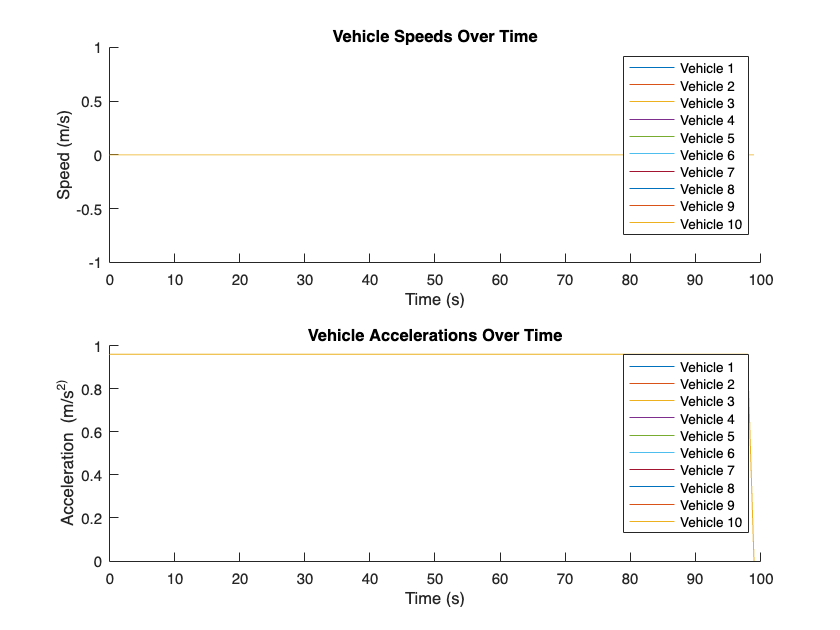

% Initial conditions
d = zeros(num_iterations, num_vehicles);

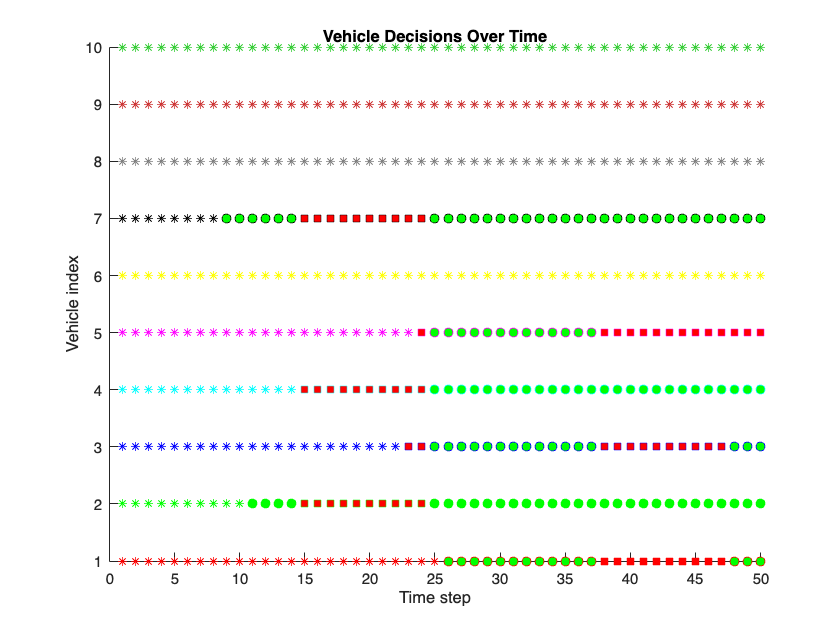

v = zeros(num_iterations, num_vehicles);
a_IDM = zeros(num_iterations, num_vehicles);
s = 10 * ones(num_vehicles, 1);  % initial gap to the leading vehicle (m)

% Set initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions (m)
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds (m/s)
v_lead(1, :) = rand(1, num_vehicles)* 10;  % speed of the leading vehicle (m/s)

% Simulate over time
for k = 1:num_iterations-1
    for i = 1:num_vehicles
        delta_v = v(k, i) - v_lead;
        a_IDM(k, i) = intelligent_driver_model(v(k, i), delta_v, s(i), params);
        v(k+1, i) = v(k, i) + a_IDM(k, i) * dt;
        d(k+1, i) = d(k, i) + v(k, i) * dt + 0.5 * a_IDM(k, i) * dt^2;
    end
end

% Visualization
figure;
subplot(3,1,1);
hold on;
for i = 1:num_vehicles
    plot(0:dt:(num_iterations-1)*dt, d(:, i));
end
hold off;
xlabel('Time (s)');
ylabel('Position (m)');
title('Vehicle Positions Over Time');
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));

subplot(3,1,2);
hold on;
for i = 1:num_vehicles
    plot(0:dt:(num_iterations-1)*dt, v(:, i));
end
hold off;
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Vehicle Speeds Over Time');
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));

subplot(3,1,3);
hold on;
for i = 1:num_vehicles
    plot(0:dt:(num_iterations-1)*dt, a(:, i));
end

hold off;
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
title('Vehicle Accelerations Over Time');
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));


# decision

% Initialize states
d = zeros(num_iterations, num_vehicles);
v = zeros(num_iterations, num_vehicles);
T_elapsed = zeros(num_iterations, num_vehicles);
D = strings(num_iterations, num_vehicles);
S = strings(num_iterations, 1);

% Initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds

% Generate traffic signal states
[traffic_signal_states, ~] = generate_traffic_signal_states(num_iterations, red_time, yellow_time, green_time, num_vehicles);
S(:, 1) = traffic_signal_states;

% Simulate over time
for k = 1:num_iterations-1
    % Simulate vehicle positions and speeds (simple linear model for example)
    d(k+1, :) = d(k, :) + v(k, :);
    v(k+1, :) = v(k, :) + (rand(1, num_vehicles) - 0.5); % Random acceleration
    
    % Calculate decisions
    D(k+1, :) = decision_making(d(k, :), d(k+1, :), v(k, :), v(k+1, :), S(k), S(k+1), T_elapsed(k, :), T_elapsed(k+1, :), D(k, :), probability_stop);
end

% Plot results
figure;
hold on;
colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k', [0.5 0.5 0.5], [0.8 0.2 0.2], [0.2 0.8 0.2]};

for i = 1:num_vehicles
    for k = 1:num_iterations
        if D(k, i) == "stop"
            plot(k, i, 's', 'Color', colors{i}, 'MarkerFaceColor', 'r'); % Red square for stop
        elseif D(k, i) == "go"
            plot(k, i, 'o', 'Color', colors{i}, 'MarkerFaceColor', 'g'); % Green circle for go
        else
            plot(k, i, '*', 'Color', colors{i}); % Star for undecided or other states
        end
    end
end

xlabel('Time step');
ylabel('Vehicle index');
title('Vehicle Decisions Over Time');
hold off;